inputimage=imread("flower.jpg")

inputimage = 500×650×3 uint8 array
inputimage(:,:,1) =

   156   155   154   153   154   153   153   153   150   149   150   147   145   141   140   138   140   139   140   140   138   136   133   131   128   128   127   125   129   135   136   132   137   135   140   148   154   160   168   176   182   187   196   199   201   202   204   204   201   200   199   199   198   195   192   188   177   173   167   165   163   161   159   158   157   154   147   142   139   136   133   131   135   138   146   153   158   163   171   175   181   185   192   198   205   210   216   219   216   215   214   214   211   208   202   198   187   182   182   183   185   185   183   179   177   174   169   167   165   164   161   159   161   160   160   158   158   156   156   155   159   160   161   160   162   162   165   166   165   166   168   167   165   164   164   163   166   163   162   161   160   159   156   155   154   151   152   149   146   141   139   138   137   138   136   135   133  

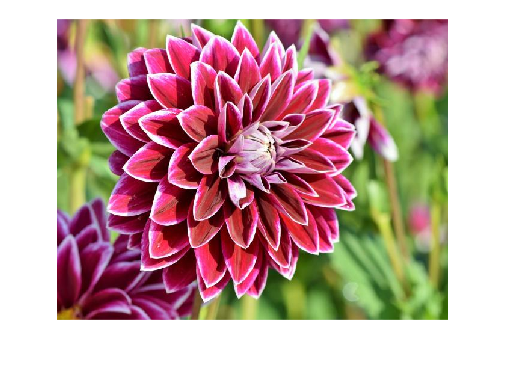

I=double(inputimage);

R=I(:,:,1);
G=I(:,:,2);
B=I(:,:,3);

[U1,S1,V1]=svd(R);
[U2,S2,V2]=svd(G);
[U3,S3,V3]=svd(B);

Blocksize= 4;
S1(Blocksize+1:125,Blocksize+1:125)=0;
S2(Blocksize+1:125,Blocksize+1:125)=0;
S3(Blocksize+1:125,Blocksize+1:125)=0;

VT1=V1';
VT2=V2';
VT3=V3';



outputimageR=U1(:,1:Blocksize)*S1(1:Blocksize,1:Blocksize)*VT1(1:Blocksize,:);
outputimageG=U2(:,1:Blocksize)*S2(1:Blocksize,1:Blocksize)*VT2(1:Blocksize,:);
outputimageB=U3(:,1:Blocksize)*S3(1:Blocksize,1:Blocksize)*VT3(1:Blocksize,:);


Reconstructedimage=cat(3,outputimageR,outputimageG,outputimageB);

absolutedifference=I-Reconstructedimage;

PSNR=psnr(Reconstructedimage,I);

UU=U1(:,1:Blocksize);
SS=S1(:,1:Blocksize);
VV=V1(:,1:Blocksize);

structurearrayUU=whos("UU");
structurearraySS=whos("SS");
structurearrayVV=whos("VV");

sizeofo=3*(structurearrayUU.bytes+structurearraySS.bytes+structurearrayVV.bytes);

structurearrayi=whos('I');
sizeofi=structurearrayi.bytes;
CR=sizeofo/sizeofi;

figure,imshow(I/255)

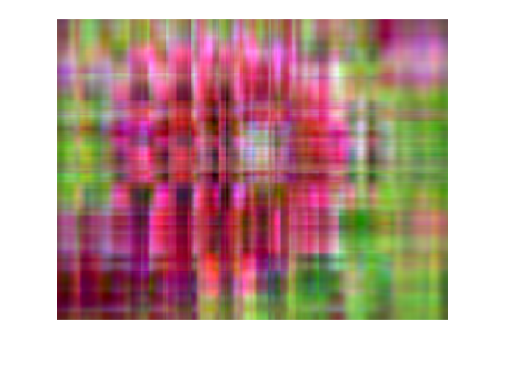

figure,imshow(Reconstructedimage/255)

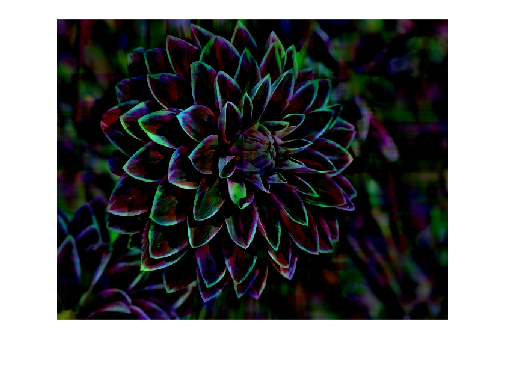

figure,imshow(absolutedifference/255)